# 数值计算 上机作业 Chapter2

### 李宇豪    21305412

对于 $f(x)=(x-1)(x-2)(x-3)$，改写为迭代格式：


$$x_{k+1}=\varphi(x_k)=-\frac{1}{2}(x^3_k-6x^2_k+9x_k-6)$$


fun=@(x) -0.5*(x^3-6*x^2+9*x-6);

计算可得   

                 
$$\varphi'(1)=0$$
   
$$\varphi''(1)\neq0$$


                 
$$\varphi'(2)\neq0$$


                 
$$\varphi'(3)=0$$
   
$$\varphi''(3)\neq0$$


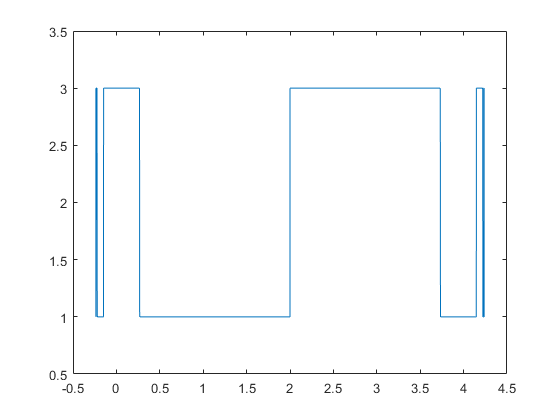

result=[];
i=-5;
while i < 5
    [x_star,~]=iterate1(fun,i);
    result=[result x_star];
    i=i+1e-4;
end
plot(linspace(-5,5,length(result)),result)

显然这图里能看出 $x=1$和 $x=3$的收敛域

$x=2$时不收敛

读取临界点

IF = ischange(result);
indices = find(IF==1);
points = -5 + indices * 1e-4

points =    -0.2358   -0.2355   -0.2334   -0.2211   -0.1476    0.2681    2.0001    3.7322    4.1479    4.2214    4.2337    4.2358    4.2361


局部收敛域只考虑一个邻域，因此可以得到

$x=1$的收敛域为 $(0.2681, 2)$

$x=3$的收敛域为 $(2, 3.7322)$

不动点迭代法

function [x_star, k] = iterate1(fun, x0, ep, Nmax)
if nargin<4 
    Nmax=100;end
if nargin<3 
    ep=1e-7;end
x=x0; x0=x+2*ep; k=0;
while abs(x0-x)>ep && k<Nmax
    x0=x; x=feval(fun, x0);
    k=k+1;
end

x_star=x;
if k==Nmax 
    warning("已达迭代次数上限");end
end